## Proyecto 3 Estadística - Modelos de regresión

### Nicolas Vargas Flores 1001368855

### Jader Stalyn Chingall Atis

#### Universidad de Antioquia

## Primera parte - Análisis exploratorio de datos (AED)

Se carga la base de datos "`datos_state.csv`".

BD = readtable("datos_state.csv");

Para calculas las estadísticas descriptivas pertinentes al proyecto se utiliza la herramienta "*Compute by group*".

% Compute group summary
AED_stats = groupsummary(BD,"Life_Exp",1,["mean","median","mode","max","min", ...
    "std","var","nummissing"],true(1,9))

AED_stats = 1×74 table
    disc_Life_Exp    GroupCount    mean_Population    median_Population    mode_Population    max_Population    min_Population    std_Population    var_Population    nummissing_Population    mean_Income    median_Income    mode_Income    max_Income    min_Income    std_Income    var_Income    nummissing_Income    mean_Illiteracy    median_Illiteracy    mode_Illiteracy    max_Illiteracy    min_Illiteracy    std_Illiteracy    var_Illiteracy    nummissing_Illiteracy    mean_Life_Exp    median_Life_Exp

Con la información recopilada en "AED_stats" se procede a presentar las estadísticas de los datos.

varNames = AED_stats.Properties.VariableNames;

% La información se almacena en una tabla
statsTable = table('Size', [9 8], 'VariableTypes', repmat({'double'}, 1, 8), ...
    'VariableNames', {'Means', 'Medians', 'Modes', 'Maxs', 'Mins', 'Stds', 'Vars', ...
    'Nummissings'}, 'RowNames', {'Population', 'Illiteracy', 'Income', 'Life_Exp', ...
    'Murder', 'HS_Grad', 'Frost', 'Area', 'Density_pob'});

% Cada fila es una estadística de cada variable
for i = 1:length(varNames)
    if startsWith(varNames{i}, 'mean_')
        statsTable.('Means')(varNames{i}(6:end)) = AED_stats.(varNames{i});
    elseif startsWith(varNames{i}, 'median_')
        statsTable.('Medians')(varNames{i}(8:end)) = AED_stats.(varNames{i});
    elseif startsWith(varNames{i}, 'mode_')
        statsTable.('Modes')(varNames{i}(6:end)) = AED_stats.(varNames{i});
    elseif startsWith(varNames{i}, 'max_')
        statsTable.('Maxs')(varNames{i}(5:end)) = AED_stats.(varNames{i});
    elseif startsWith(varNames{i}, 'min_')
        statsTable.('Mins')(varNames{i}(5:end)) = AED_stats.(varNames{i});
    elseif startsWith(varNames{i}, 'std_')
        statsTable.('Stds')(varNames{i}(5:end)) = AED_stats.(varNames{i});
    elseif startsWith(varNames{i}, 'var_')
        statsTable.('Vars')(varNames{i}(5:end)) = AED_stats.(varNames{i});
    elseif startsWith(varNames{i}, 'nummissing_')
        statsTable.('Nummissings')(varNames{i}(12:end)) = AED_stats.(varNames{i});
    end
end

disp(statsTable)

                   Means     Medians     Modes        Maxs        Mins       Stds         Vars       Nummissings
                   ______    _______    _______    __________    _______    _______    __________    ___________

    Population     4246.4    2838.5         365         21198        365     4464.5    1.9932e+07         0     
    Illiteracy       1.17      0.95         0.6           2.8        0.5    0.60953       0.37153         0     
    Income         4435.8      4519        3098          6315       3098     614.47    3.7757e+05         0     
    Life_Exp       70.879    70.675       70.55          73.6      67.96     1.3424         1.

Para tener una vista general de los datos se realizan histogramas para cada variable.

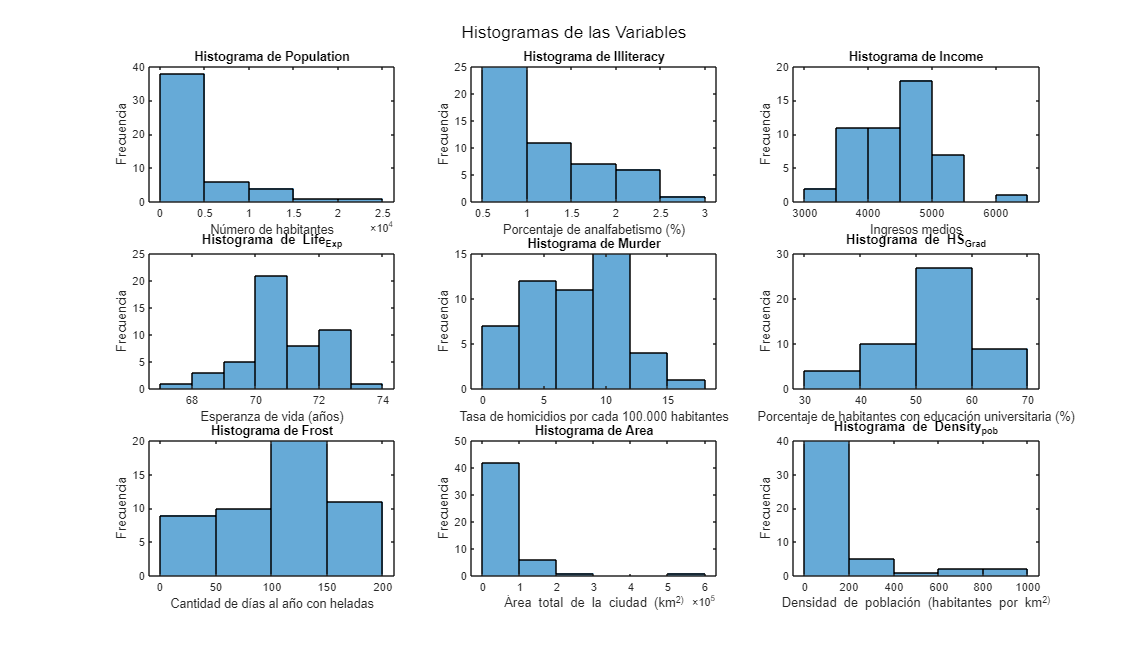

% Histogramas
variables = {'Population', 'Illiteracy', 'Income', 'Life_Exp', 'Murder', ...
    'HS_Grad', 'Frost', 'Area', 'Density_pob'};

figure;
for i = 1:length(variables)
    subplot(3, 3, i);
    histogram(BD.(variables{i}));
    title(['Histograma de ' variables{i}]);
    switch variables{i}
        case 'Population'
            xlabel('Número de habitantes');
        case 'Illiteracy'
            xlabel('Porcentaje de analfabetismo (%)');
        case 'Income'
            xlabel('Ingresos medios');
        case 'Life_Exp'
            xlabel('Esperanza de vida (años)');
        case 'Murder'
            xlabel('Tasa de homicidios por cada 100.000 habitantes');
        case 'HS_Grad'
            xlabel('Porcentaje de habitantes con educación universitaria (%)');
        case 'Frost'
            xlabel('Cantidad de días al año con heladas');
        case 'Area'
            xlabel('Área total de la ciudad (km^2)');
        case 'Density_pob'
            xlabel('Densidad de población (habitantes por km^2)');
    end
    ylabel('Frecuencia');
end
sgtitle('Histogramas de las Variables');
set(gcf, 'Position', get(0, 'Screensize')); % Maximiza la figura

Los siguientes diagramas de cajas y bigotes serán útiles para visualizar la distribución de la información, y ser conscientes de los posibles outliers que hay en cada variable.

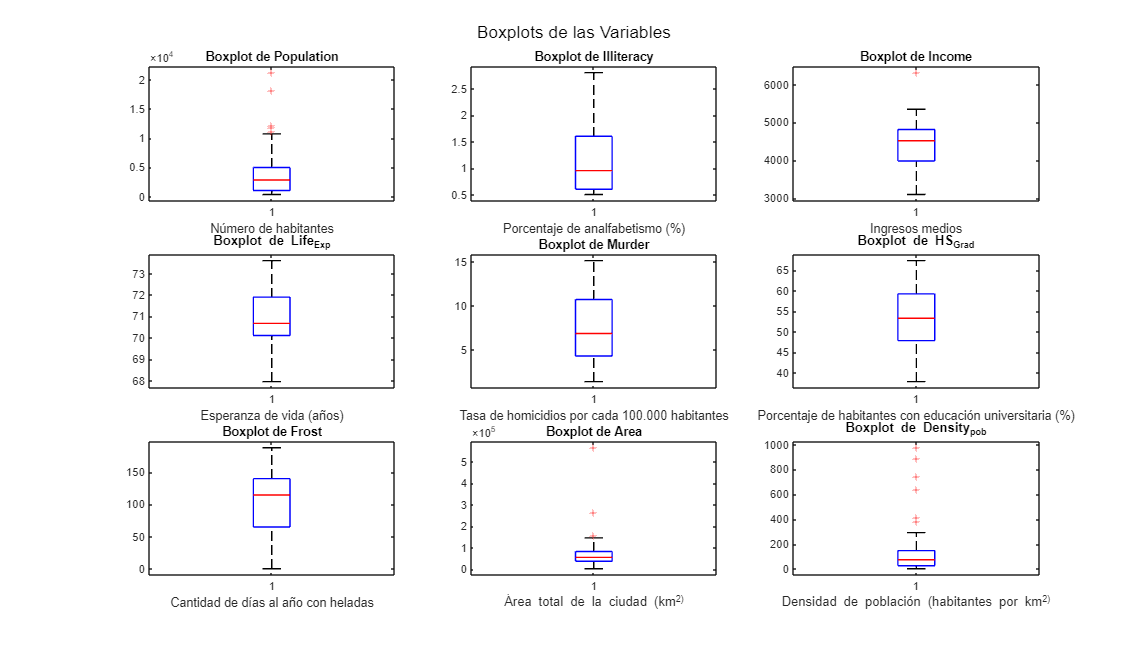

% Boxplots
figure;
for i = 1:length(variables)
    subplot(3, 3, i);
    boxplot(BD.(variables{i}));
    title(['Boxplot de ' variables{i}]);
    switch variables{i}
        case 'Population'
            xlabel('Número de habitantes');
        case 'Illiteracy'
            xlabel('Porcentaje de analfabetismo (%)');
        case 'Income'
            xlabel('Ingresos medios');
        case 'Life_Exp'
            xlabel('Esperanza de vida (años)');
        case 'Murder'
            xlabel('Tasa de homicidios por cada 100.000 habitantes');
        case 'HS_Grad'
            xlabel('Porcentaje de habitantes con educación universitaria (%)');
        case 'Frost'
            xlabel('Cantidad de días al año con heladas');
        case 'Area'
            xlabel('Área total de la ciudad (km^2)');
        case 'Density_pob'
            xlabel('Densidad de población (habitantes por km^2)');
    end
end
sgtitle('Boxplots de las Variables');
set(gcf, 'Position', get(0, 'Screensize')); % Maximiza la figura

### Distribuciones

Notese que en los diagramas anteriores se ve que existen muchos datos outliers que aumentan la varianza significativamente, lo cual hace que la normalidad de los datos se vea gravemente afectada. Con el propósito de encontrar una distribución estadística que nos sirva para realizar los posteriores análisis; se transforman los datos para atenuar el peso de los outliers dentro del desenlace estadístico.

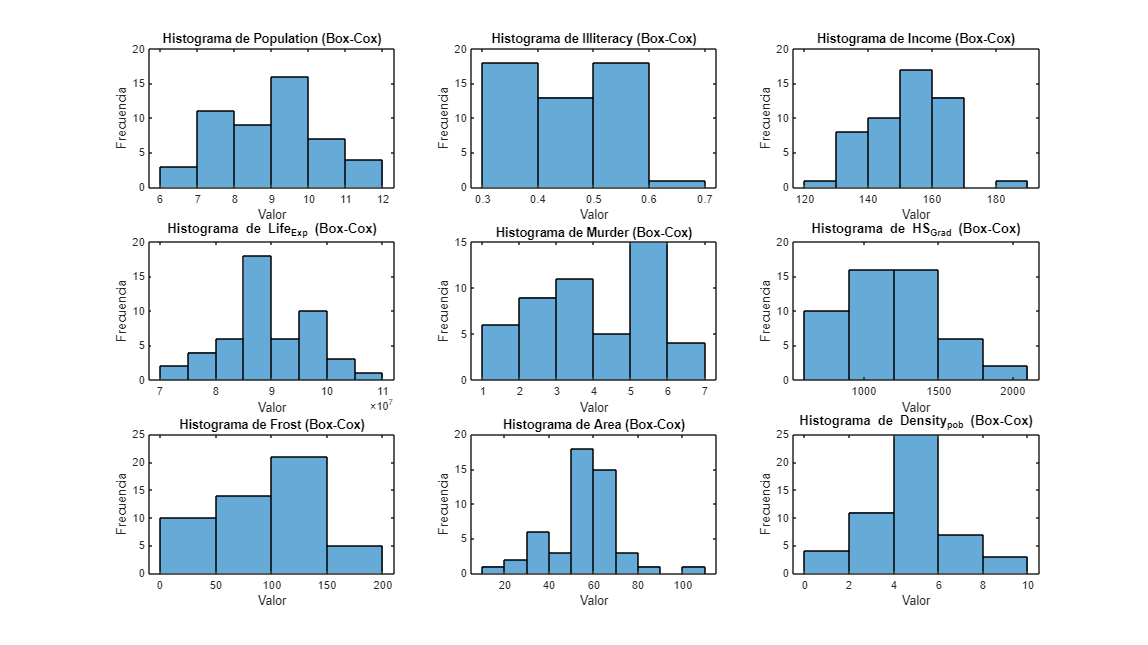

% Librería de estadísticas
import statistics.*

figure;
% Box-Cox transformation
for i = 1:length(variables)
    % Aplicar la transformación de Box-Cox
    [transformed, lambda] = boxcox(BD.(variables{i})+1);
    
    % Se almacenan los datos en una tabla
    BD.([variables{i} '_boxcox']) = transformed;
    
    % Histogramas con los datos transformados
    subplot(3, 3, i);
    histogram(transformed);
    title(['Histograma de ' variables{i} ' (Box-Cox)']);
    xlabel('Valor');
    ylabel('Frecuencia');
end
set(gcf, 'Position', get(0, 'Screensize'));

La transformación de Box-Cox es una técnica estadística que se utiliza para transformar datos no normales en una forma que se aproxime a la normalidad. La transformación de Box-Cox se define como:


$$y(\lambda )=\left\lbrace \begin{array}{ll}
\frac{y^{\lambda } -1}{\lambda } & \textrm{si}\;\lambda \not= 0,\\
\ln (y) & \textrm{si}\;\lambda =0,
\end{array}\right.$$


donde `y` es la variable que se desea transformar y `λ` es el parámetro de transformación. El valor de `λ` se elige de manera que maximice la verosimilitud de los datos transformados.

Para este estudio la transformación de Box-Cox es útil porque ayuda a estabilizar la varianza, hace que los datos se comporten más como una distribución normal, mejora la validez de las medidas de asociación (como la correlación) y hace que los patrones en los datos y los residuos sean más fáciles de identificar. Box-Cox es especialmente útil para manejar los valores atípicos.

Una herramienta útil para visualizar la normalidad de un conjunto de datos son los gráficos Q-Q, presentados a continuación.

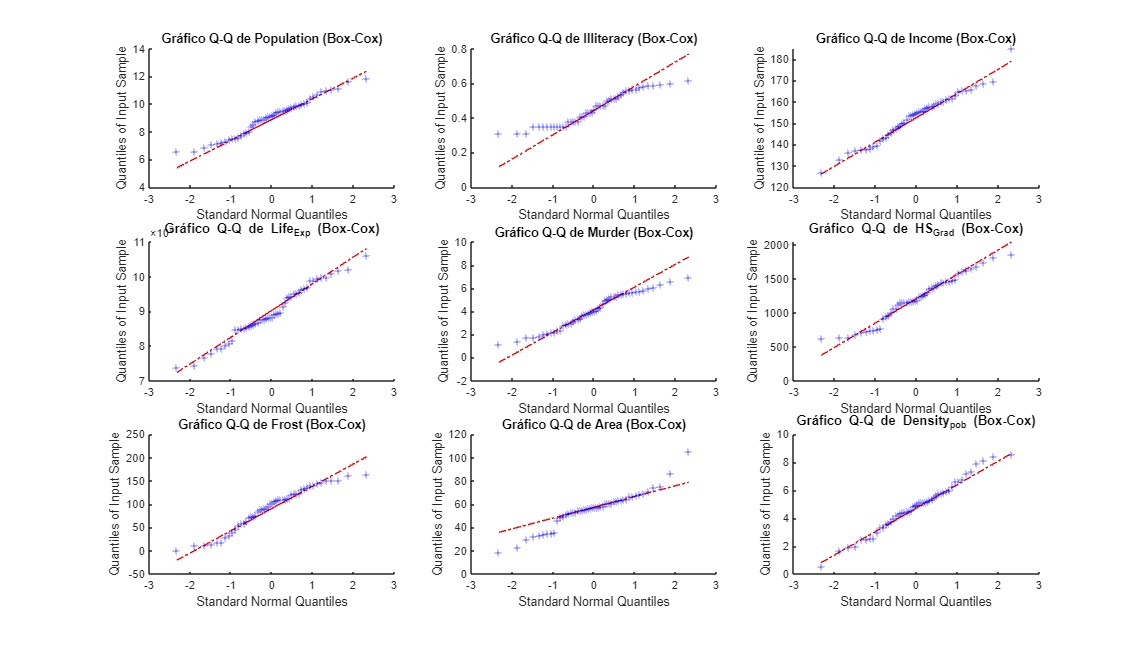

figure;
% Gráficos Q-Q para cada variable
for i = 1:length(variables)
    subplot(3, 3, i);
    qqplot(BD.([variables{i} '_boxcox']));
    title(['Gráfico Q-Q de ' variables{i} ' (Box-Cox)']);
end
set(gcf, 'Position', get(0, 'Screensize'));

### Contrastando la normalidad

Es importante conocer las distribuciones de los datos; especialmente conocer cuales de ellos tienen una distribución Gaussiana. Esta sección realizará una prueba de Shapiro-Wilk para cada variable para evaluar si los datos siguen una distribución normal. 

results = table('Size', [length(variables) 4], ...
    'VariableTypes', {'string', 'logical', 'double', 'string'}, ...
    'VariableNames', {'Variable', 'H0_Rejected', 'P_Value', 'Distribution'});

% Se descargó prueba swtest.m en File Exchange MatLab
for i = 1:length(variables)
    % Aplicar la prueba de Shapiro-Wilk
    [h, p] = swtest(BD.([variables{i} '_boxcox']));
    
    % Determinar si los datos siguen una distribución normal
    if h == 0
        distribution = 'Gaussiana';
    else
        distribution = 'No Gaussiana';
    end
    
    results(i, :) = {variables{i}, h, p, distribution};
end

disp(results)

      Variable       H0_Rejected     P_Value      Distribution 
    _____________    ___________    _________    ______________

    "Population"        false         0.38817    "Gaussiana"   
    "Illiteracy"        true        0.0037886    "No Gaussiana"
    "Income"            false         0.33775    "Gaussiana"   
    "Life_Exp"          false         0.50064    "Gaussiana"   
    "Murder"            false        0.063933    "Gaussiana"   
    "HS_Grad"           false         0.13314    "Gaussiana"   
    "Frost"             true         0.045587    "No Gaussiana"
    "Area"              true        0.0074883    "No Gaussiana"
    "Density_pob"       false         0.87122    "Gaussiana"   



## Segunda parte - Estadística inferencial

### Modelos univariados

A continuación se van a realizar múltiples modelos de regresión lineal univariada teniendo únicamente en cuenta aquellas variables que sigan una distribución Gaussiana.

La normalidad de las variables es una suposición importante que subyace en muchos modelos y técnicas. Los modelos de regresión lineal, por ejemplo, asumen que los errores (es decir, las diferencias entre las respuestas observadas y las predichas) siguen una distribución normal. Esta suposición permite realizar inferencias estadísticas válidas a partir del modelo. Si una variable no sigue una distribución normal, puede violar esta suposición y hacer que las inferencias del modelo sean menos precisas o incluso inválidas. 

Lo anterior es para argumentar la necesidad de considerar solo las variables que siguen una distribución normal. Eso garantiza que las inferencias basadas en el modelo de regresión lineal sean válidas y precisas.

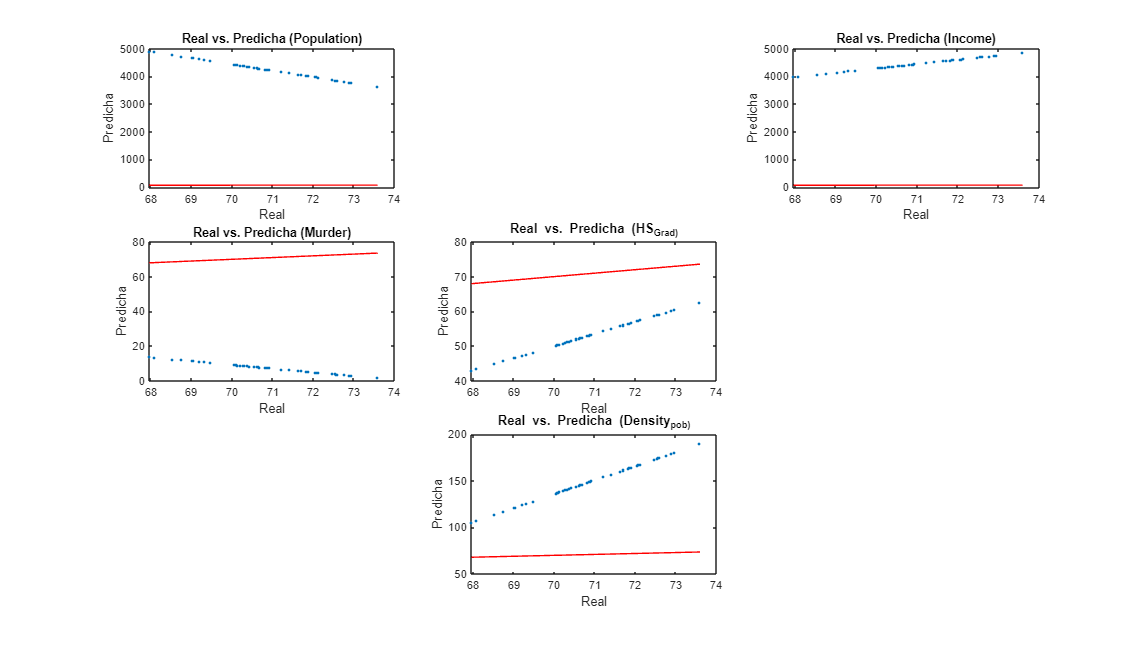

% Lista de variables predictoras
predictors = {'Population', 'Illiteracy', 'Income', 'Murder', ...
    'HS_Grad', 'Frost', 'Area', 'Density_pob'};

% Variable de salida
response = 'Life_Exp';

results = table('Size', [length(predictors) 4], ...
    'VariableTypes', {'string', 'double', 'double', 'double'}, ...
    'VariableNames', {'Variable', 'R_Squared', 'RMSE', 'P_Value'});

figure;
for i = 1:length(predictors)
    % Aplicar la prueba de Shapiro-Wilk
    [h, p] = swtest(BD.([predictors{i} '_boxcox']));
    
    % Si los datos siguen una distribución normal, se consideran en el modelo de regresión lineal
    if h == 0
        lm = fitlm(BD, [predictors{i} ' ~ ' response]);
        
        % Almacenar los resultados en la tabla
        results(i, :) = {predictors{i}, lm.Rsquared.Ordinary, lm.RMSE, lm.Coefficients.pValue(2)};
        
        % Obtener las predicciones del modelo
        predictions = predict(lm, BD);
        
        % Gráfico de las respuestas reales Vs las predicciones
        subplot(3, 3, i);
        plot(BD.(response), predictions, '.');
        hold on;
        plot([min(BD.(response)), max(BD.(response))], [min(BD.(response)), max(BD.(response))], 'r');
        hold off;
        title(['Real vs. Predicha (' predictors{i} ')']);
        xlabel('Real');
        ylabel('Predicha');
    end
end
set(gcf, 'Position', get(0, 'Screensize'));


disp(results)

      Variable       R_Squared     RMSE      P_Value  
    _____________    _________    ______    __________

    "Population"     0.0046311    4500.3       0.63866
    <missing>                0         0             0
    "Income"           0.11577    583.79      0.015617
    "Murder"           0.60972    2.3301    2.2601e-11
    "HS_Grad"          0.33898    6.6349    9.1961e-06
    <missing>                0         0             0
    <missing>                0         0             0
    "Density_pob"    0.0082922    222.37        0.5294



### Modelo lineal multivariado

Teniendo en cuenta las variables predictoras seleccionadas en la sección anterior, se propone el siguiente modelo de regresión para predecir la esperanza de vida de una población.

% Lista de variables predictoras
predictors = {'Population', 'Income', 'Murder', 'HS_Grad', 'Density_pob'};

% Variable de salida
response = 'Life_Exp';

% Fórmula del modelo
formula = [response ' ~ ' strjoin(predictors, ' + ')];

% Modelo de regresión lineal multivariado
lm = fitlm(BD, formula);

% Mostrar las métricas de evaluación del modelo
disp(lm)

Linear regression model:
    Life_Exp ~ 1 + Population + Income + Murder + HS_Grad + Density_pob

Estimated Coefficients:
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)         70.754        1.0782      65.619    1.5461e-45
    Population      7.2306e-05    2.8527e-05      2.5347      0.014888
    Income          2.9401e-05    0.00027565     0.10666       0.91555
    Murder             -0.2821      0.039706     -7.1049    8.0271e-09
    HS_Grad           0.034965      0.022465      1.5565       0.12676
    Density_pob    -0.00059249    0.00063008    -0.94035       0.35217


Number of observations: 50, Error degrees of freedom: 44
Root Mean Sq


% Predicciones del modelo
predictions = predict(lm, BD);

También se realiza un gráfico de dispersión que muestre la relación entre las variables predichas con las reales.

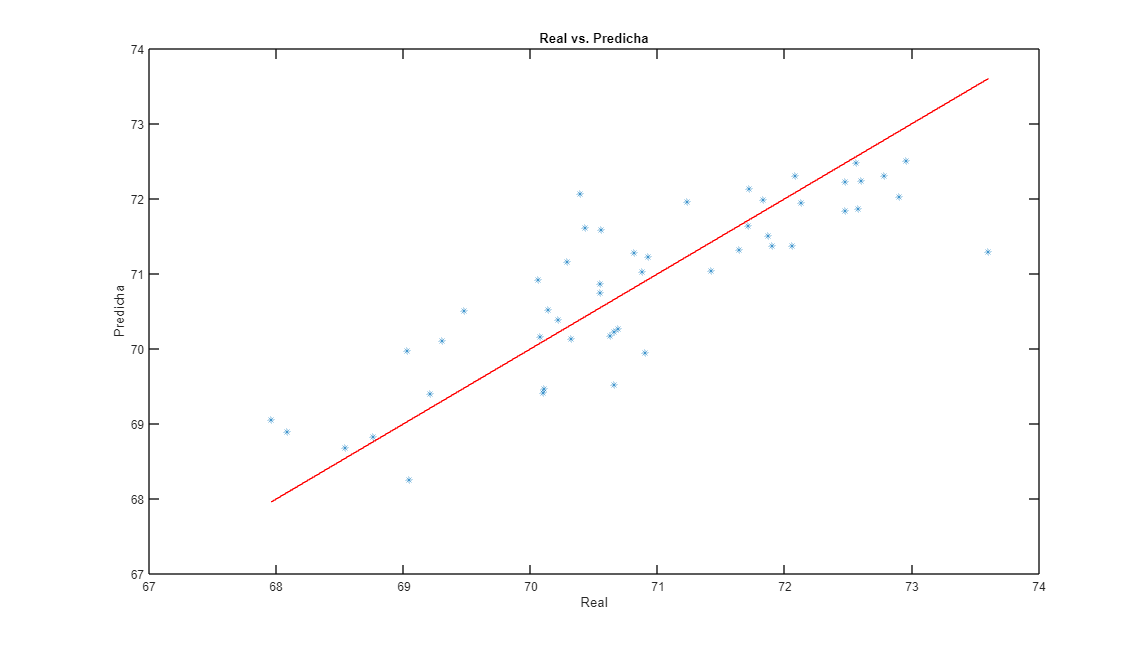

% Gráfico de las respuestas reales vs. las predicciones
figure;
plot(BD.(response), predictions, '*');
hold on;
plot([min(BD.(response)), max(BD.(response))], [min(BD.(response)), max(BD.(response))], 'r');
hold off;
title('Real vs. Predicha');
xlabel('Real');
ylabel('Predicha');

set(gcf, 'Position', get(0, 'Screensize'));

### Purga de variables

Se va realizar otro modelo multivariado de regresión lineal pero únicamente considerando las variables que sean verdaderamente predictoras. Los supuestos de normalidad de confirmaron utilizando la prueba de Shapiro-Wilk.

Ahora resta realizar una prueba de homogenidad de varianzas y un test de correlación para verificar los supuestos del modelo de regresión lineal multivariado. En esta sección se realizará la prueba de Levene para la homogenidad de varianzas.

% Lista de variables predictoras
predictors = {'Population', 'Income', 'Murder', 'HS_Grad', 'Density_pob'};

leveneResults = table('Size', [length(predictors) 3], ...
    'VariableTypes', {'string', 'double', 'string'}, ...
    'VariableNames', {'Variable', 'P_Value', 'Homogeneity'});

for i = 1:length(predictors)
    % Verificar si la variable existe en la tabla
    if ~any(strcmp(BD.Properties.VariableNames, predictors{i}))
        fprintf('La variable %s no existe en la tabla BD.\n', predictors{i});
        continue;
    end
    
    % Verificar el tipo de datos
    if ~isa(BD.(predictors{i}), 'double')
        fprintf('La variable %s no es de tipo double.\n', predictors{i});
        continue;
    end
    
    % Limpiar los datos
    data = BD.(predictors{i});
    data = data(~isnan(data) & ~isinf(data));  % Eliminar NaNs e Infs
    
    % Verificar si los datos son constantes
    if range(data) == 0
        fprintf('La variable %s es constante y se omitirá de la prueba de Levene.\n', predictors{i});
        continue;
    end
    
    % Dividir los datos en dos grupos
    medianValue = median(data);
    group1 = data(data <= medianValue);
    group2 = data(data > medianValue);
    
    % Prueba de Levene
    p = vartestn([group1; group2], [ones(size(group1)); 2*ones(size(group2))], ...
                 'TestType', 'LeveneAbsolute', 'Display', 'off');
    
    % Determinar si los datos pasan la verificación de supuestos
    if p > 0.05
        homogeneity = 'Pass';
    else
        homogeneity = 'Fail';
    end
    
    leveneResults(i, :) = {predictors{i}, p, homogeneity};
end

disp(leveneResults)

      Variable             P_Value           Homogeneity
    _____________    ____________________    ___________

    "Population"     9.17936038618155e-06      "Fail"   
    "Income"            0.484303246290379      "Pass"   
    "Murder"            0.768150794332981      "Pass"   
    "HS_Grad"         0.00256092404202033      "Fail"   
    "Density_pob"     4.7588443015055e-06      "Fail"   



### Interpretación de la prueba Levene

La prueba de Levene se realizó para verificar la homogeneidad de las varianzas entre dos grupos para cada variable predictora. Los grupos se formaron dividiendo los datos de cada variable en dos basándose en la mediana. Esta es una forma común de dividir los datos cuando no se dispone de una categorización natural.

Los resultados de la prueba de Levene se interpretan de la siguiente manera: un valor p menor a 0.05 indica que se rechaza la hipótesis nula de igualdad de varianzas, lo que significa que las varianzas de los dos grupos son significativamente diferentes. Por otro lado, un valor p mayor a 0.05 indica que no hay suficiente evidencia para rechazar la hipótesis nula, lo que sugiere que las varianzas de los dos grupos son iguales.

En este caso, las variables `Population`, `HS_Grad` y `Density_pob` tienen valores p muy pequeños (menores a 0.05), lo que indica que las varianzas de los dos grupos para estas variables son significativamente diferentes. Esto sugiere que la distribución de estos datos está sesgada y tiene valores atípicos. Por otro lado, las variables `Income` y `Murder` tienen valores p mayores a 0.05, lo que indica que las varianzas de los dos grupos para estas variables no son significativamente diferentes, lo que sugiere que estos datos son homogéneos.

### Matriz de correlación

Esta sección ayudará a verificar qué relación tienen las variables entre sí. Es un proceso importante para elegir finalmente cuáles serán las variables predictoras en el modelo de regresión final.

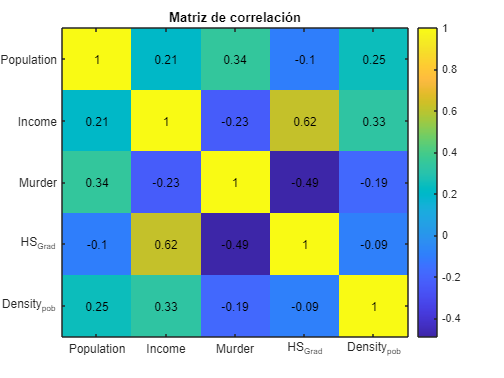

predictors = {'Population', 'Income', 'Murder', 'HS_Grad', 'Density_pob'};

% Matriz de correlación
corrMatrix = corr(BD{:, predictors});

% Mapa de calor de la matriz de correlación
figure;
imagesc(corrMatrix);
colorbar;
title('Matriz de correlación');
xticks(1:length(predictors));
yticks(1:length(predictors));
xticklabels(predictors);
yticklabels(predictors);

% Coeficientes de correlación al mapa de calor
for i = 1:length(predictors)
    for j = 1:length(predictors)
        text(j, i, num2str(round(corrMatrix(i, j), 2)), 'HorizontalAlignment', 'center');
    end
end

### Modelo de regresión final

Se pueden seleccionar las variables predictoras para el modelo multivariado basándose en los resultados de la prueba de Levene y la matriz de correlación. En este caso, las variables `Income` y `Murder` pasaron la prueba de Levene, lo que indica que sus varianzas son homogéneas. Además, según la matriz de correlación, estas dos variables no están fuertemente correlacionadas entre sí, lo que es bueno porque evita el problema de la multicolinealidad.

Por lo tanto, se usa `Income` y `Murder` como las variables predictoras en el siguiente modelo multivariado.

% Lista de variables predictoras finales
predictors = {'Income', 'Murder'};

% Variable de salida
response = 'Life_Exp';

% Fórmula del modelo
formula = [response ' ~ ' strjoin(predictors, ' + ')];

% Modelo de regresión lineal multivariado
lm = fitlm(BD, formula);

% Métricas de evaluación del modelo
disp(lm)

Linear regression model:
    Life_Exp ~ 1 + Income + Murder

Estimated Coefficients:
                         Estimate                   SE                   tStat                 pValue       
                   ____________________    ____________________    _________________    ____________________

    (Intercept)         71.225581467592       0.967395161335469     73.6261502169046    3.31942949898273e-50
    Income         0.000370463882283167    0.000197297362787839     1.87769302665003      0.0666361919095996
    Murder           -0.269759441125457      0.0328408492348385    -8.21414328224158    1.22248947421689e-10


Number of observations: 50, Error degrees of freedom: 47
Root Mean Squared Error: 0.826
R-squared: 0.637,  Adjusted R-Squared: 0.622
F-statistic vs. constant model: 41.2, p-value =

## Conclusiones finales

El modelo de regresión lineal multivariado que se ajustó tiene como variables predictoras `Income` (Ingresos) y `Murder` (Asesinatos), y como variable de respuesta `Life_Exp` (Esperanza de Vida). Observando las métricas de evaluación del modelo se puede concluir lo siguiente:

- **Intercepto (**`Intercept`**)**: El intercepto del modelo es aproximadamente 71.23. Esto significa que, cuando los ingresos y la tasa de asesinatos son cero, la esperanza de vida media estimada es de alrededor de 71.23 años.

- **Ingresos (**`Income`**)**: El coeficiente para los ingresos es aproximadamente 0.00037. Esto significa que, manteniendo constante la tasa de asesinatos, un aumento de una unidad en los ingresos se asocia con un aumento de 0.00037 unidades en la esperanza de vida. Sin embargo, el valor p para los ingresos es aproximadamente 0.067, que es mayor que el umbral comúnmente utilizado de 0.05. Esto sugiere que los ingresos no son significativamente predictivos de la esperanza de vida en este modelo.

- **Asesinatos (**`Murder`**)**: El coeficiente para los asesinatos es aproximadamente -0.27. Esto significa que, manteniendo constante los ingresos, un aumento de una unidad en la tasa de asesinatos se asocia con una disminución de 0.27 unidades en la esperanza de vida. El valor p para los asesinatos es muy pequeño (aproximadamente 1.22e-10), lo que indica que los asesinatos son un predictor significativo de la esperanza de vida en este modelo.

- **R-cuadrado y R-cuadrado ajustado**: El R-cuadrado del modelo es aproximadamente 0.637, lo que indica que alrededor del 63.7% de la variabilidad en la esperanza de vida se puede explicar por los ingresos y la tasa de asesinatos. El R-cuadrado ajustado, que tiene en cuenta el número de predictores en el modelo, es aproximadamente 0.622.

- **Valor-p del modelo (**`p-value`**)**: el valor p del modelo es extremadamente pequeño (4.56e-11), lo que indica que el modelo es significativo.

A continuación podemos ver gráficamente los valores del modelo final Vs los valores reales, agregando el error entre dichos valores.

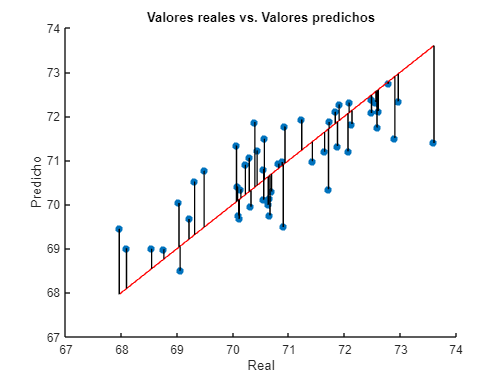

% Obtener los valores predichos
predicted = predict(lm, BD);

% Obtener los valores reales
real = BD.Life_Exp;

% Crear el gráfico de dispersión
figure;
scatter(real, predicted, 'filled');  % Los puntos son grandes y están rellenos
hold on;

% Añadir la línea de identidad (valores predichos = valores reales)
plot([min(real), max(real)], [min(real), max(real)], 'r');

% Añadir las líneas de error
for i = 1:length(real)
    line([real(i), real(i)], [real(i), predicted(i)], 'Color', 'k');
end

% Etiquetas y título
xlabel('Real');
ylabel('Predicho');
title('Valores reales vs. Valores predichos');

hold off;